clc; clear;
path = 'Circuits/RLC.txt';
circuit = Circuit(path);

% Symbolic
ELAB.analyze(circuit)

Symbolic analysis successful (1.75183 sec).


ELAB.transfer(circuit, 3, 2, false)

Transfer function calculated successfully (1.246370e-02 sec).
Findings were saved to object properties.

$$ans = \frac{v_{2}}{v_{3}}=\frac{R_{1}\,\mathrm{Vin}+L_{1}\,\mathrm{Vin}\,s+C_{2}\,R_{1}\,R_{2}\,\mathrm{Vs}\,s+C_{1}\,L_{1}\,R_{1}\,\mathrm{Vin}\,s^{2}+C_{2}\,L_{1}\,R_{1}\,\mathrm{Vin}\,s^{2}+C_{2}\,L_{1}\,R_{2}\,\mathrm{Vs}\,s^{2}}{\mathrm{Vin}\,\left(R_{1}+L_{1}\,s+C_{1}\,L_{1}\,R_{1}\,s^{2}+C_{2}\,L_{1}\,R_{1}\,s^{2}+C_{2}\,L_{1}\,R_{2}\,s^{2}+C_{2}\,R_{1}\,R_{2}\,s+C_{1}\,C_{2}\,L_{1}\,R_{1}\,R_{2}\,s^{3}\right)}$$

% Numerical
ELAB.evaluate(circuit)


Numerical evaluation successful (0.82007 sec).


ELAB.transfer(circuit, 3, 2, true)

Transfer function calculated successfully (1.687715e+00 sec).
Findings were saved to object properties.
ans =
 
    1100 s^2 + 100000 s + 1e11
  ------------------------------
  s^3 + 2100 s^2 + 1e09 s + 1e11
 
Continuous-time transfer function.



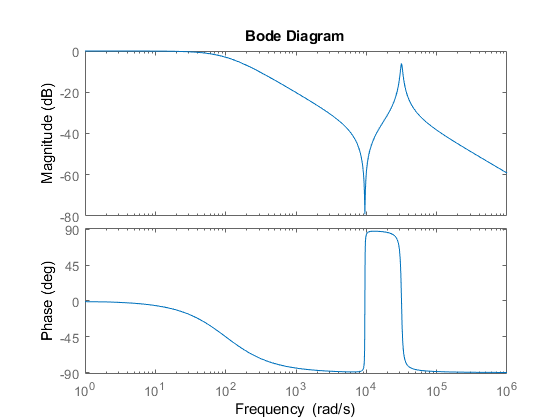

ELAB.bode_plot(circuit) % Try other plots.